# 4. Sensor Modelling and State Estimation

## 4.1 Overview

So far we were able to build a digital twin of the robot and control it using a nested controls architecture. Thereby we provited from the fact that all the states could be measured in the digital twin. Quite often, this is not the case in reality and we have to develop the controls using avialable sensor readings. In our case we have access to an IMU unit and the motor encoders. These sensor readings are discrete and often subject to noise and drift. In order to derive the state information needed for our controls approach we will apply sensor fusion algorithms. This allows to mitigate the impact of drift on the state estimation.

## 4.2 IMU Sensor Model

To develop the state estimation algorithm we make use of the IMU sensor model block im Simulink. As input it takes measurements from the ideal transformation sensor of Simscape Multibody.

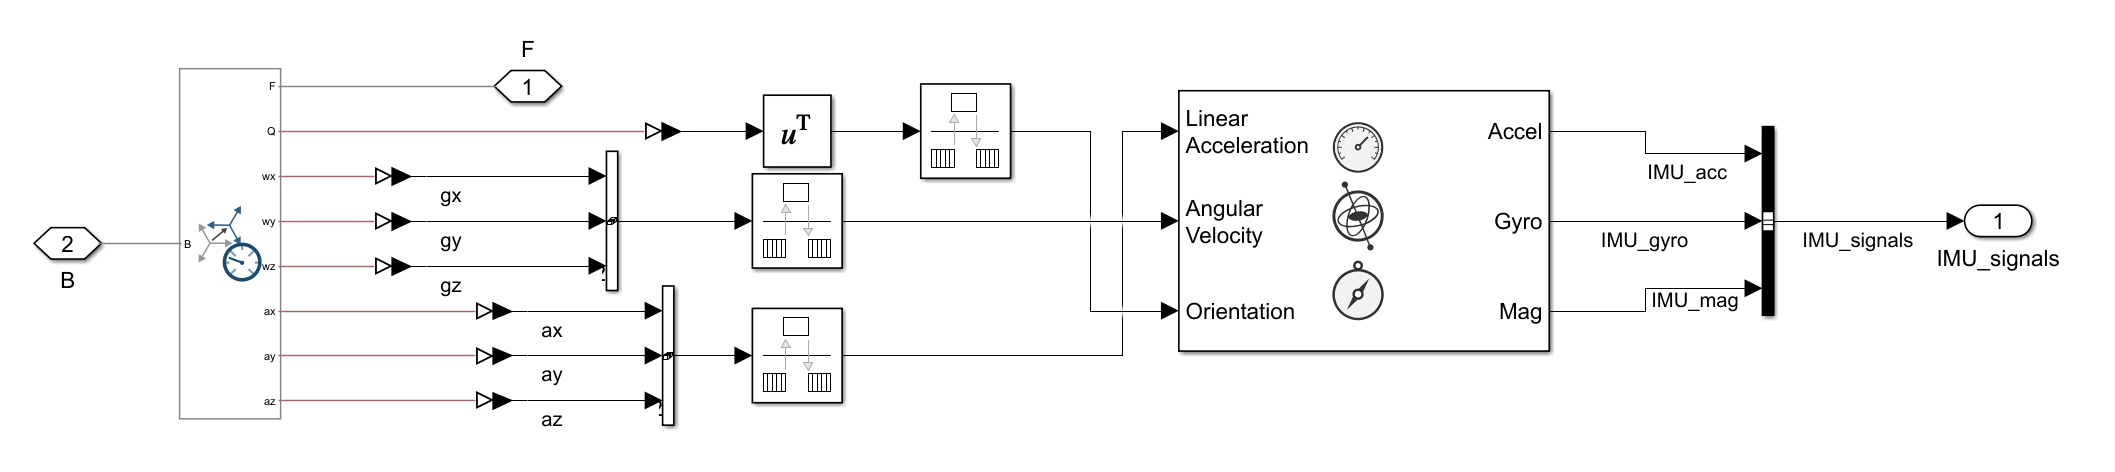

 The properties of the IMU block can be configured from specs of the real sensor. In our case we are mainly interested in the Accelerator and Gyroscope settings.

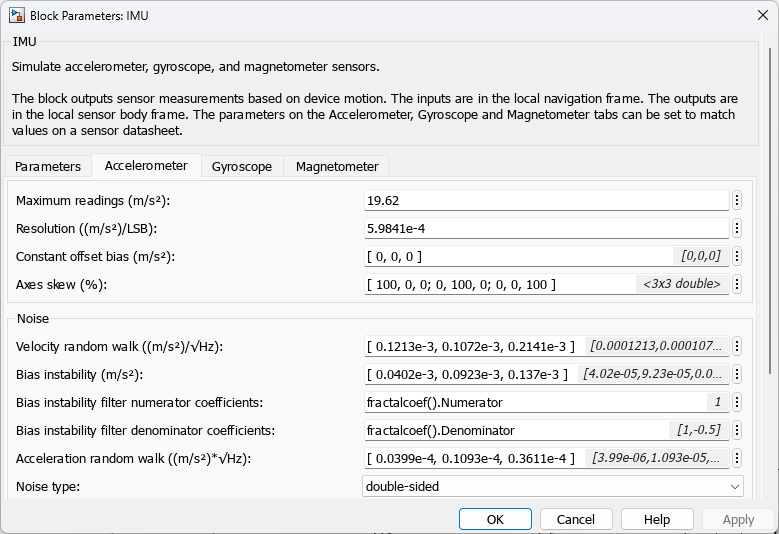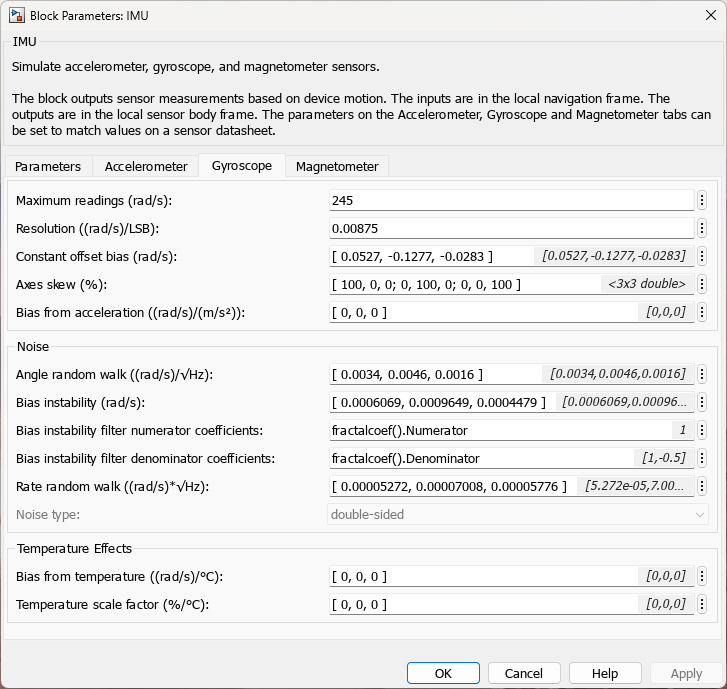

## 4.2 Estimating Sensor Characteristics

The table below shows how the sensor characterisitics have been determined. The values given in the table have been taken from the specifications. They have been used for initization.

To get accuracte parameters it is advised to take sensor readings over a certain amount of time (i.e. 1h) and analyse them to assess drift and noise.

The measurements can be done using Simulink.

open_system('Ex6_IMU_SensorCharacterization') %run simulation for ...
% Note the implementation of the sensor. Having too many individual calls to I2C addresses slows down the Raspberry Pi control logic. → Combine calls where possible.


For the sake of following this tutorial you can also take prerecorded data (should record longer time scale and validate them...)

%if you do not have time to measure the sensor outputs please feel free to load the prerecorded data here
load('SensorReadingsForAnalysis.mat')
acc_init.data=logsout{5}.Values.Data; %acc
gyro_init.data=logsout{6}.Values.Data; %gyro

The sensor measurements are modeled as $\Omega(t)=\Omega_{Ideal}(t)+Bias_{N}(t)+Bias_{B}(t) + Bias_{K}(t)$, with the three noise parameters *N* (angle/velocity random walk), *K* (rate/acceleration random walk), and *B* (bias instability)

The Allan variance can be used to estimate the noise parameters. To streamline this, we use a helper function that implements the code from this example: [Inertial sensor noise analysis using allan variance](https://www.mathworks.com/help/fusion/ug/inertial-sensor-noise-analysis-using-allan-variance.html).

[N_acc,K_acc,B_acc]= SensorNoiseAnalysis(acc_init.data,100);
[N_gyro,K_gyro,B_gyro]= SensorNoiseAnalysis(gyro_init.data,100);

#### Accelerometer Noise Parameters

fprintf(['Velocity Random Walk     (N_acc): [%s]\n' 'Bias Instability         (B_acc): [%s]\n' 'Acceleration Random Walk (K_acc): [%s]\n'], ...
         sprintf(' %.6g', N_acc(:)), sprintf(' %.6g', B_acc(:)), sprintf(' %.6g', K_acc(:)));

Velocity Random Walk     (N_acc): [ 0.000128179 0.000118083 0.000323581]
Bias Instability         (B_acc): [ 9.56374e-05 8.11964e-05 0.00018152]
Acceleration Random Walk (K_acc): [ 2.15742e-05 2.45469e-05 2.3134e-05]


#### Gyroscope Noise Parameters

fprintf(['Angle Random Walk (N_gyro): [%s]\n' 'Bias Instability  (B_gyro): [%s]\n' 'Rate Random Walk  (K_gyro): [%s]\n'], ...
         sprintf(' %.6g', N_gyro(:)), sprintf(' %.6g', B_gyro(:)), sprintf(' %.6g', K_gyro(:)));

Angle Random Walk (N_gyro): [ 0.00040676 0.000559575 0.000221182]
Bias Instability  (B_gyro): [ 0.000116578 0.000162326 7.66216e-05]
Rate Random Walk  (K_gyro): [ 1.36031e-05 2.50092e-05 1.48597e-05]


#### Gyroscope Offsets

In idle position the gyroscope should indicate 0 rotation. However, typically there is an offset, that we should consider for calibration. This can be determined by taking the median of a measurement. 

median(gyro_init.data)

ans =     0.0492   -0.1261   -0.0305


## Sensitivity on External Acceleration (optional)

In addition to the above parameters, one could also consider to take into account that the sensor readings are affected by external acceleration. This can be evaluated by taking measurements with different board orientations. One can then evaluate the impact of the acceleration, in this case the gravity, on the sensors. The following lines of code illustrate some sensor readings where this influence can be observed. However, we do not dive into the details here to quantify this effect.

load("GyroNoiseEval_20250805.mat") %measurements available
%even though I'm not sure anymore if I used these measurements, they can be
%used to determine the offset of the gyro. -> needed for the IMU  block

## Difference of mean and median value depending on orientation (for all axes)

gyro.dup=flat_up{2}.Values.Data;
gyro.tup=flat_up{2}.Values.Time;
gyro.tdown=flat_down{2}.Values.Time;
gyro.ddown=flat_down{2}.Values.Data;

plot(gyro.tup, gyro.dup(:,3), gyro.tdown, gyro.ddown(:,3))
legend({'up','down'})

mean(gyro.dup(:,1))-mean(gyro.ddown(:,1))
mean(gyro.dup(:,2))-mean(gyro.ddown(:,2))
mean(gyro.dup(:,3))-mean(gyro.ddown(:,3))
median(gyro.dup(:,1))-median(gyro.ddown(:,1))
median(gyro.dup(:,2))-median(gyro.ddown(:,2))
median(gyro.dup(:,3))-median(gyro.ddown(:,3))

gyro.dstup=standing_up{2}.Values.Data;
gyro.tstup=standing_up{2}.Values.Time;
gyro.tstdown=standing_down{2}.Values.Time;
gyro.dstdown=standing_down{2}.Values.Data;

plot(gyro.tstup, gyro.dstup(:,2), gyro.tstdown, gyro.dstdown(:,2))
legend({'up','down'})

mean(gyro.dstup(:,1))-mean(gyro.dstdown(:,1))
mean(gyro.dstup(:,2))-mean(gyro.dstdown(:,2))
mean(gyro.dstup(:,3))-mean(gyro.dstdown(:,3))
median(gyro.dstup(:,1))-median(gyro.dstdown(:,1))
median(gyro.dstup(:,2))-median(gyro.dstdown(:,2))
median(gyro.dstup(:,3))-median(gyro.dstdown(:,3))

gyro.dUSBup=side_USB_up{2}.Values.Data;
gyro.tUSBup=side_USB_up{2}.Values.Time;
gyro.tUSBdown=side_USB_down{2}.Values.Time;
gyro.dUSBdown=side_USB_down{2}.Values.Data;

plot(gyro.tUSBup, gyro.dUSBup(:,1), gyro.tUSBdown, gyro.dUSBdown(:,1))
legend({'up','down'})

mean(gyro.dUSBup(:,1))-mean(gyro.dUSBdown(:,1))
mean(gyro.dUSBup(:,2))-mean(gyro.dUSBdown(:,2))
mean(gyro.dUSBup(:,3))-mean(gyro.dUSBdown(:,3))
median(gyro.dUSBup(:,1))-median(gyro.dUSBdown(:,1))
median(gyro.dUSBup(:,2))-median(gyro.dUSBdown(:,2))
median(gyro.dUSBup(:,3))-median(gyro.dUSBdown(:,3))